# Header

File name "IBVS_Monocular.m" ELE00142M Machine Vision and Human Machine Interaction Lab 3: Visual Servoing with MATLAB

clear
clc
close all

## Configuration Visualization

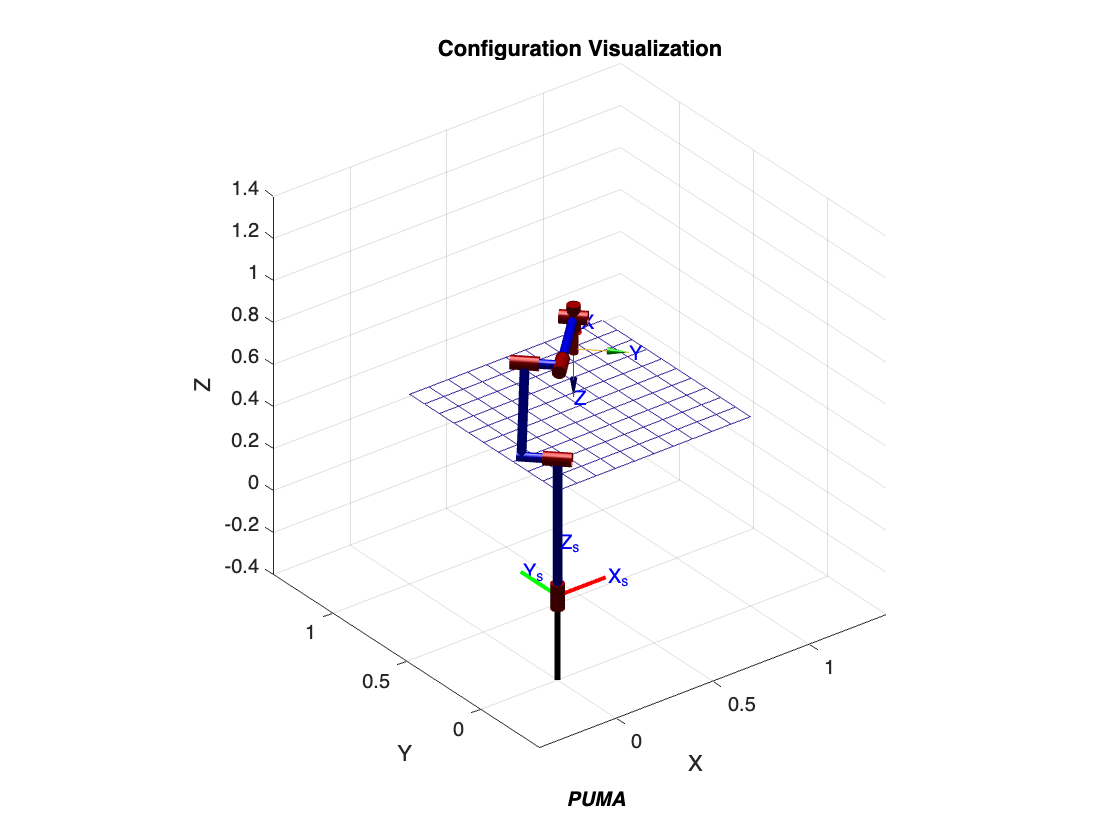

% 6R PUMA type robot arm and Body frame (Using Robotics Toolbox)
figure(1)
title('Configuration Visualization')
L(1) = Link([ 000*pi/180  0.65000 0.00000   -090*pi/180    0    000*pi/180]);
L(2) = Link([ 000*pi/180  0.15000 0.40000    000*pi/180    0    000*pi/180]);
L(3) = Link([ 000*pi/180 -0.15000 0.00000   -090*pi/180    0   -090*pi/180]);
L(4) = Link([ 000*pi/180  0.40000 0.00000    090*pi/180    0    000*pi/180]);
L(5) = Link([ 000*pi/180  0.00000 0.00000   -090*pi/180    0    000*pi/180]);
L(6) = Link([ 000*pi/180  0.15000 0.00000    000*pi/180    0    000*pi/180]);
PUMA = SerialLink(L,'name','PUMA');
theta_initial = [045*pi/180  -75*pi/180  075*pi/180  000*pi/180  090*pi/180  000*pi/180];
PUMA.plot(theta_initial,'scale',0.3);

% Space frame
Ts = [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1;];
hold on
trplot(Ts,'thick',2,'frame','s','length',0.25,'rgb')

% Task space
xlim([-0.4 1.4])
ylim([-0.4 1.4])
zlim([-0.4 1.4])
length = 1;
height = 0.5;
x_length = 0:length/10:length;
y_length = 0:length/10:length;
[x_grid,y_grid] = meshgrid(x_length,y_length);
mesh(x_grid,y_grid,height.*ones(11,11));


% Camera frame
% Camera frame is coincident with the body frame
% Do not need visualization

## Camera calibration

% intrinsic parameter matric of camera
a = [800    0  800   0;
    0  800  800   0;
    0    0    1   0;];

## Set Target point & 4 interest points

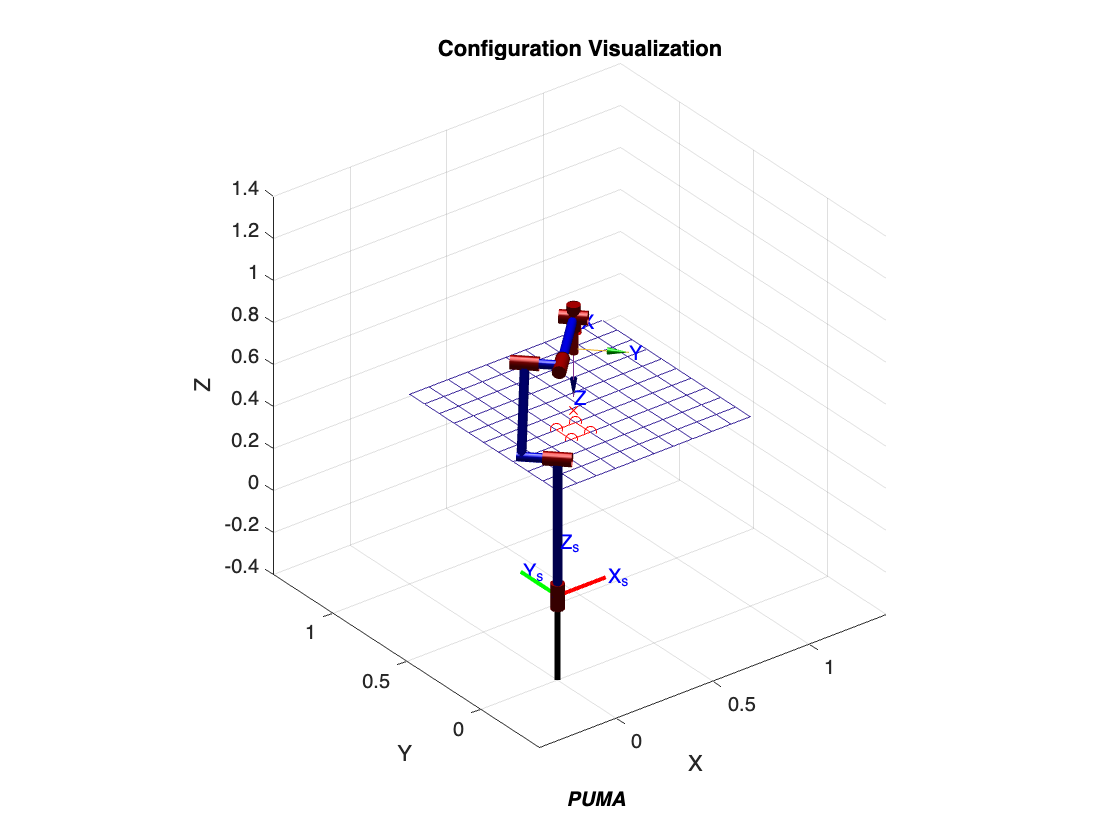

% Target point
X_target = [0.35, 0.35, height + 0.1]';

% Place target point in task space
plot3(X_target(1,1),X_target(2,1),X_target(3,1),'rx')

% 4 interest points in task space
X_s_i_set = [X_target(1,1)-0.05  X_target(1,1)-0.05  X_target(1,1)+0.05   X_target(1,1)+0.05;
    X_target(2,1)-0.05  X_target(2,1)+0.05  X_target(2,1)-0.05   X_target(2,1)+0.05;
    X_target(3,1)-0.1   X_target(3,1)-0.1   X_target(3,1)-0.1    X_target(3,1)-0.1;];

% Place 4 interest points in task space
figure(1)
line(X_s_i_set(1,[1 2]),X_s_i_set(2,[1 2]),X_s_i_set(3,[1 2]),'color','r');
line(X_s_i_set(1,[2 4]),X_s_i_set(2,[2 4]),X_s_i_set(3,[2 4]),'color','r');
line(X_s_i_set(1,[4 3]),X_s_i_set(2,[4 3]),X_s_i_set(3,[4 3]),'color','r');
line(X_s_i_set(1,[3 1]),X_s_i_set(2,[3 1]),X_s_i_set(3,[3 1]),'color','r');
plot3(X_s_i_set(1,1),X_s_i_set(2,1),X_s_i_set(3,1),'ro')
plot3(X_s_i_set(1,2),X_s_i_set(2,2),X_s_i_set(3,2),'ro')
plot3(X_s_i_set(1,3),X_s_i_set(2,3),X_s_i_set(3,3),'ro')
plot3(X_s_i_set(1,4),X_s_i_set(2,4),X_s_i_set(3,4),'ro')

## Desired Parameter for robot control

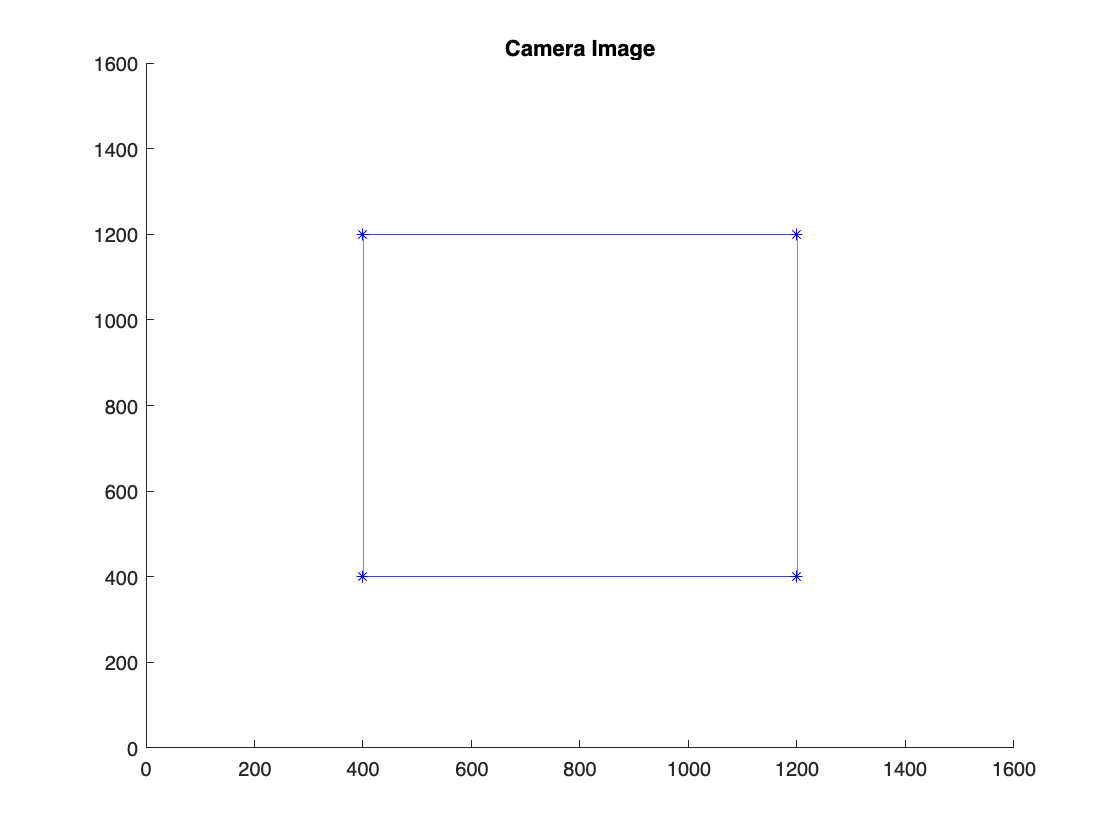

% Set desired pixel coordinates of 4 interest points
m_c_i_star = [ 400  400 1200 1200;
    1200  400 1200  400;];

% Plot desired position of 4 interest points in camera image
figure(2)
title('Camera Image')
xlim([0 1600])
ylim([0 1600])
hold on
plot(m_c_i_star(1,1),m_c_i_star(2,1),'b*')
plot(m_c_i_star(1,2),m_c_i_star(2,2),'b*')
plot(m_c_i_star(1,3),m_c_i_star(2,3),'b*')
plot(m_c_i_star(1,4),m_c_i_star(2,4),'b*')
line(m_c_i_star(1,[1 2]),m_c_i_star(2,[1 2]),'color','b');
line(m_c_i_star(1,[2 4]),m_c_i_star(2,[2 4]),'color','b');
line(m_c_i_star(1,[4 3]),m_c_i_star(2,[4 3]),'color','b');
line(m_c_i_star(1,[3 1]),m_c_i_star(2,[3 1]),'color','b');


% Calculate desired visual feature
s_star = Calculate_s(m_c_i_star,a); %equation 2.9

% Set desired Z axis height
z_star = 0.1;

% Termination conditions of iteration
error_max = 0.001;

% Upper limit of angular velocity of robot manipulator joints (rad/s)
joint_velocity_max = 0.5;

% Cameras report 25 images per second
Hz = 25;

% Current angles of robot manipulator joints
theta_current = theta_initial;

% Current pose of robot end-effector
T_s_e_current = PUMA_fkine(theta_current); % This is a 4 by 4 homogenous transformation matrix [Rot Transl; 0 1]

% Set Lambda
Lambda = 10;
% setriteration idex
i = 1;

## VS Loop Start

while true

## Error (i.e. distance between current position and desired position of end-effector)

Extract current position from the T_s_e_current Require a bit of robotics knowledge, see [https://modernrobotics.northwestern.edu/nu-gm-book-resource/3-3-1-homogeneous-transformation-matrices/](https://modernrobotics.northwestern.edu/nu-gm-book-resource/3-3-1-homogeneous-transformation-matrices/) if you do not understand the concept of homogenous transformation matrix

    %------ Your code here -----------------------------------------
    current_position = T_s_e_current(1:3,end)
    %---------------------------------------------------------------
    % Calculate the distance between current and target position X_target
    % Construct a stopping condition for the for loop with this error (hint: using error_max)
    % Otherwise THIS LOOP will run FOREVER!!!!
    %------ Your code here -----------------------------------------
    distance = norm(current_position - X_target)
    if distance <= error_max
        break
    end
    %---------------------------------------------------------------

current_position =     0.3560
    0.3560
    0.8864


distance = 0.2865

current_position =     0.3560
    0.3560
    0.8851


distance = 0.2852

current_position =     0.3560
    0.3559
    0.8838


distance = 0.2839

current_position =     0.3560
    0.3559
    0.8824


distance = 0.2825

current_position =     0.3560
    0.3558
    0.8809


distance = 0.2810

current_position =     0.3560
    0.3557
    0.8793


distance = 0.2795

current_position =     0.3560
    0.3556
    0.8777


distance = 0.2778

current_position =     0.3560
    0.3556
    0.8760


distance = 0.2761

current_position =     0.3560
    0.3555
    0.8742


distance = 0.2743

current_position =     0.3560
    0.3554
    0.8724


distance = 0.2725

current_position =     0.3559
    0.3553
    0.8704


distance = 0.2705

current_position =     0.3559
    0.3553
    0.8684


distance = 0.2685

current_position =     0.3559
    0.3552
    0.8662


distance = 0.2663

current_position =     0.3559
    0.3551
    0.8639


distance = 0.2641

current_position =     0.3558
    0.3550
    0.8616


distance = 0.2617

current_position =     0.3558
    0.3549
    0.8591


distance = 0.2592

current_position =     0.3558
    0.3548
    0.8565


distance = 0.2566

current_position =     0.3557
    0.3547
    0.8537


distance = 0.2538

current_position =     0.3557
    0.3546
    0.8508


distance = 0.2509

current_position =     0.3556
    0.3545
    0.8478


distance = 0.2479

current_position =     0.3556
    0.3544
    0.8445


distance = 0.2446

current_position =     0.3555
    0.3543
    0.8411


distance = 0.2412

current_position =     0.3554
    0.3542
    0.8375


distance = 0.2376

current_position =     0.3553
    0.3541
    0.8337


distance = 0.2338

current_position =     0.3553
    0.3540
    0.8296


distance = 0.2297

current_position = 3×1
    0.3552
    0.3539
    0.8252


distance = 0.2253

current_position = 3×1
    0.3551
    0.3537
    0.8206


distance = 0.2207

current_position = 3×1
    0.3549
    0.3536
    0.8155


distance = 0.2156

current_position = 3×1
    0.3548
    0.3534
    0.8101


distance = 0.2102

current_position = 3×1
    0.3547
    0.3533
    0.8042


distance = 0.2043

current_position = 3×1
    0.3545
    0.3531
    0.7978


distance = 0.1979

current_position = 3×1
    0.3543
    0.3529
    0.7907


distance = 0.1908

current_position = 3×1
    0.3541
    0.3527
    0.7828


distance = 0.1829

current_position = 3×1
    0.3539
    0.3525
    0.7740


distance = 0.1740

current_position = 3×1
    0.3536
    0.3522
    0.7638


distance = 0.1639

current_position = 3×1
    0.3532
    0.3520
    0.7523


distance = 0.1523

current_position = 3×1
    0.3529
    0.3517
    0.7402


distance = 0.1403

current_position = 3×1
    0.3525
    0.3514
    0.7276


distance = 0.1276

current_position = 3×1
    0.3521
    0.3511
    0.7142


distance = 0.1143

current_position = 3×1
    0.3517
    0.3508
    0.7001


distance = 0.1001

current_position = 3×1
    0.3513
    0.3505
    0.6849


distance = 0.0849

current_position = 3×1
    0.3508
    0.3502
    0.6684


distance = 0.0685

current_position = 3×1
    0.3504
    0.3499
    0.6526


distance = 0.0526

current_position = 3×1
    0.3501
    0.3498
    0.6378


distance = 0.0378

current_position = 3×1
    0.3499
    0.3497
    0.6240


distance = 0.0240

current_position = 3×1
    0.3499
    0.3498
    0.6144


distance = 0.0144

current_position = 3×1
    0.3499
    0.3498
    0.6087


distance = 0.0087

current_position = 3×1
    0.3499
    0.3499
    0.6052


distance = 0.0052

current_position = 3×1
    0.3500
    0.3499
    0.6031


distance = 0.0031

current_position = 3×1
    0.3500
    0.3500
    0.6019


distance = 0.0019

current_position = 3×1
    0.3500
    0.3500
    0.6011


distance = 0.0011

current_position = 3×1
    0.3500
    0.3500
    0.6007


distance = 6.7383e-04

## Visual Feature & Visual Feature Error

e =     0.2949
   -0.5000
    0.4779
    0.3170
   -0.5221
   -0.3170
   -0.3391
    0.5000


e =     0.2943
   -0.4960
    0.4742
    0.3167
   -0.5184
   -0.3161
   -0.3385
    0.4966


e =     0.2939
   -0.4919
    0.4706
    0.3165
   -0.5146
   -0.3152
   -0.3379
    0.4933


e =     0.2934
   -0.4879
    0.4669
    0.3164
   -0.5108
   -0.3144
   -0.3374
    0.4898


e =     0.2930
   -0.4838
    0.4632
    0.3162
   -0.5070
   -0.3136
   -0.3368
    0.4864


e =     0.2927
   -0.4797
    0.4595
    0.3162
   -0.5031
   -0.3129
   -0.3364
    0.4829


e =     0.2924
   -0.4756
    0.4558
    0.3161
   -0.4992
   -0.3122
   -0.3359
    0.4794


e =     0.2922
   -0.4714
    0.4520
    0.3161
   -0.4953
   -0.3116
   -0.3355
    0.4759


e =     0.2919
   -0.4672
    0.4482
    0.3160
   -0.4913
   -0.3109
   -0.3350
    0.4723


e =     0.2917
   -0.4630
    0.4444
    0.3161
   -0.4873
   -0.3103
   -0.3346
    0.4687


e =     0.2916
   -0.4587
    0.4406
    0.3161
   -0.4833
   -0.3098
   -0.3343
    0.4651


e =     0.2915
   -0.4545
    0.4367
    0.3162
   -0.4792
   -0.3092
   -0.3339
    0.4614


e =     0.2914
   -0.4501
    0.4328
    0.3163
   -0.4750
   -0.3087
   -0.3336
    0.4577


e =     0.2913
   -0.4458
    0.4289
    0.3163
   -0.4708
   -0.3082
   -0.3333
    0.4539


e =     0.2913
   -0.4414
    0.4249
    0.3165
   -0.4666
   -0.3078
   -0.3329
    0.4501


e =     0.2913
   -0.4370
    0.4209
    0.3166
   -0.4622
   -0.3073
   -0.3326
    0.4462


e =     0.2913
   -0.4325
    0.4169
    0.3167
   -0.4579
   -0.3069
   -0.3323
    0.4422


e =     0.2913
   -0.4279
    0.4127
    0.3168
   -0.4534
   -0.3065
   -0.3320
    0.4382


e =     0.2913
   -0.4233
    0.4086
    0.3169
   -0.4489
   -0.3060
   -0.3316
    0.4341


e =     0.2913
   -0.4186
    0.4043
    0.3170
   -0.4443
   -0.3056
   -0.3313
    0.4300


e =     0.2913
   -0.4139
    0.4000
    0.3170
   -0.4395
   -0.3052
   -0.3309
    0.4257


e =     0.2913
   -0.4090
    0.3956
    0.3170
   -0.4347
   -0.3047
   -0.3304
    0.4213


e =     0.2913
   -0.4041
    0.3911
    0.3170
   -0.4298
   -0.3042
   -0.3299
    0.4168


e =     0.2912
   -0.3990
    0.3865
    0.3169
   -0.4247
   -0.3037
   -0.3294
    0.4122


e =     0.2911
   -0.3938
    0.3818
    0.3167
   -0.4194
   -0.3031
   -0.3287
    0.4074


e = 8×1
    0.2908
   -0.3885
    0.3769
    0.3164
   -0.4140
   -0.3024
   -0.3279
    0.4024


e = 8×1
    0.2905
   -0.3829
    0.3718
    0.3159
   -0.4083
   -0.3017
   -0.3270
    0.3972


e = 8×1
    0.2901
   -0.3771
    0.3665
    0.3153
   -0.4024
   -0.3007
   -0.3260
    0.3917


e = 8×1
    0.2895
   -0.3711
    0.3609
    0.3144
   -0.3961
   -0.2997
   -0.3246
    0.3859


e = 8×1
    0.2886
   -0.3648
    0.3550
    0.3133
   -0.3895
   -0.2984
   -0.3230
    0.3797


e = 8×1
    0.2875
   -0.3580
    0.3487
    0.3118
   -0.3823
   -0.2968
   -0.3211
    0.3731


e = 8×1
    0.2860
   -0.3507
    0.3420
    0.3098
   -0.3746
   -0.2948
   -0.3186
    0.3658


e = 8×1
    0.2840
   -0.3428
    0.3345
    0.3072
   -0.3661
   -0.2923
   -0.3155
    0.3578


e = 8×1
    0.2813
   -0.3340
    0.3262
    0.3037
   -0.3565
   -0.2891
   -0.3115
    0.3487


e = 8×1
    0.2775
   -0.3240
    0.3167
    0.2990
   -0.3454
   -0.2848
   -0.3063
    0.3381


e = 8×1
    0.2725
   -0.3125
    0.3058
    0.2925
   -0.3326
   -0.2792
   -0.2993
    0.3258


e = 8×1
    0.2660
   -0.3002
    0.2939
    0.2845
   -0.3187
   -0.2723
   -0.2908
    0.3124


e = 8×1
    0.2578
   -0.2867
    0.2809
    0.2745
   -0.3034
   -0.2637
   -0.2803
    0.2976


e = 8×1
    0.2475
   -0.2715
    0.2661
    0.2621
   -0.2861
   -0.2529
   -0.2675
    0.2807


e = 8×1
    0.2344
   -0.2539
    0.2490
    0.2465
   -0.2660
   -0.2393
   -0.2514
    0.2611


e = 8×1
    0.2173
   -0.2328
    0.2283
    0.2265
   -0.2420
   -0.2218
   -0.2310
    0.2375


e = 8×1
    0.1946
   -0.2062
    0.2023
    0.2002
   -0.2118
   -0.1984
   -0.2041
    0.2080


e = 8×1
    0.1669
   -0.1754
    0.1721
    0.1692
   -0.1777
   -0.1702
   -0.1725
    0.1744


e = 8×1
    0.1346
   -0.1405
    0.1379
    0.1340
   -0.1399
   -0.1372
   -0.1366
    0.1373


e = 8×1
    0.0963
   -0.0999
    0.0981
    0.0936
   -0.0972
   -0.0981
   -0.0954
    0.0954


e = 8×1
    0.0634
   -0.0655
    0.0644
    0.0605
   -0.0626
   -0.0646
   -0.0616
    0.0614


e = 8×1
    0.0403
   -0.0416
    0.0409
    0.0380
   -0.0393
   -0.0411
   -0.0388
    0.0386


e = 8×1
    0.0251
   -0.0259
    0.0254
    0.0235
   -0.0243
   -0.0256
   -0.0240
    0.0238


e = 8×1
    0.0154
   -0.0159
    0.0156
    0.0144
   -0.0148
   -0.0157
   -0.0146
    0.0146


e = 8×1
    0.0094
   -0.0097
    0.0095
    0.0087
   -0.0090
   -0.0095
   -0.0089
    0.0088


e = 8×1
    0.0057
   -0.0058
    0.0057
    0.0053
   -0.0054
   -0.0058
   -0.0054
    0.0053


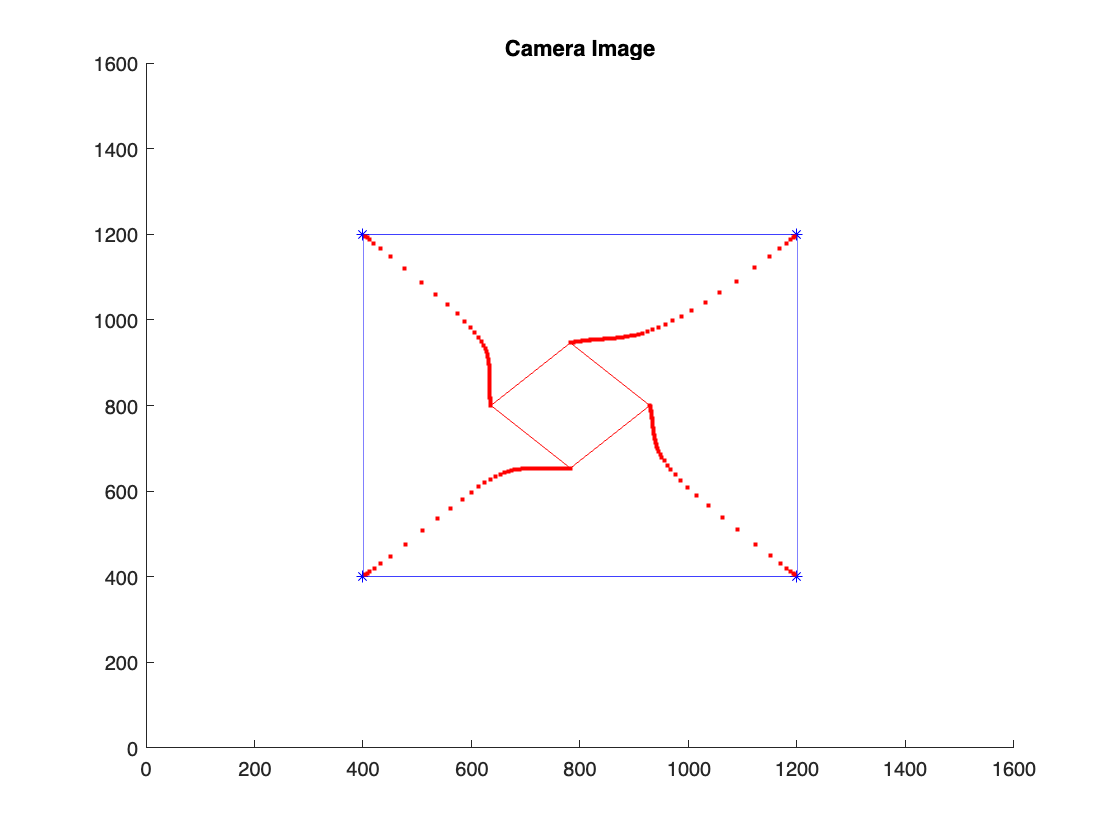

    % Get pixel coordinates of 4 interest points
    T_c_s = inv(T_s_e_current);
    m_c_i = Camera_3to2(X_s_i_set,T_c_s);
    
    % Calculate visual feature
    s = Calculate_s(m_c_i,a);
    
    % Calculate visual feature error
    %------ Your code here -----------------------------------------
    e = s - s_star
    %---------------------------------------------------------------
    figure(2) % camera image update
    plot(m_c_i(1,1),m_c_i(2,1),'r.')
    plot(m_c_i(1,2),m_c_i(2,2),'r.')
    plot(m_c_i(1,3),m_c_i(2,3),'r.')
    plot(m_c_i(1,4),m_c_i(2,4),'r.')
    if i == 1
        line(m_c_i(1,[1 2]),m_c_i(2,[1 2]),'color','r');
        line(m_c_i(1,[2 4]),m_c_i(2,[2 4]),'color','r');
        line(m_c_i(1,[4 3]),m_c_i(2,[4 3]),'color','r');
        line(m_c_i(1,[3 1]),m_c_i(2,[3 1]),'color','r');
    end

## Spatial Velocity Calculation

calculate the interaction matrix given the desire z axis value

    Lx = Calculate_Lx(s,z_star); % Your code for Calculate_Lx
    % Spatial velocity
    %------ Your code here, calculate spatial velocity--------------
    % Hint: equation (4) in the paper
    v = -Lambda * pinv(Lx) * e;
    %---------------------------------------------------------------

## Inverse Velocity Kinematics of Robot Manipulator

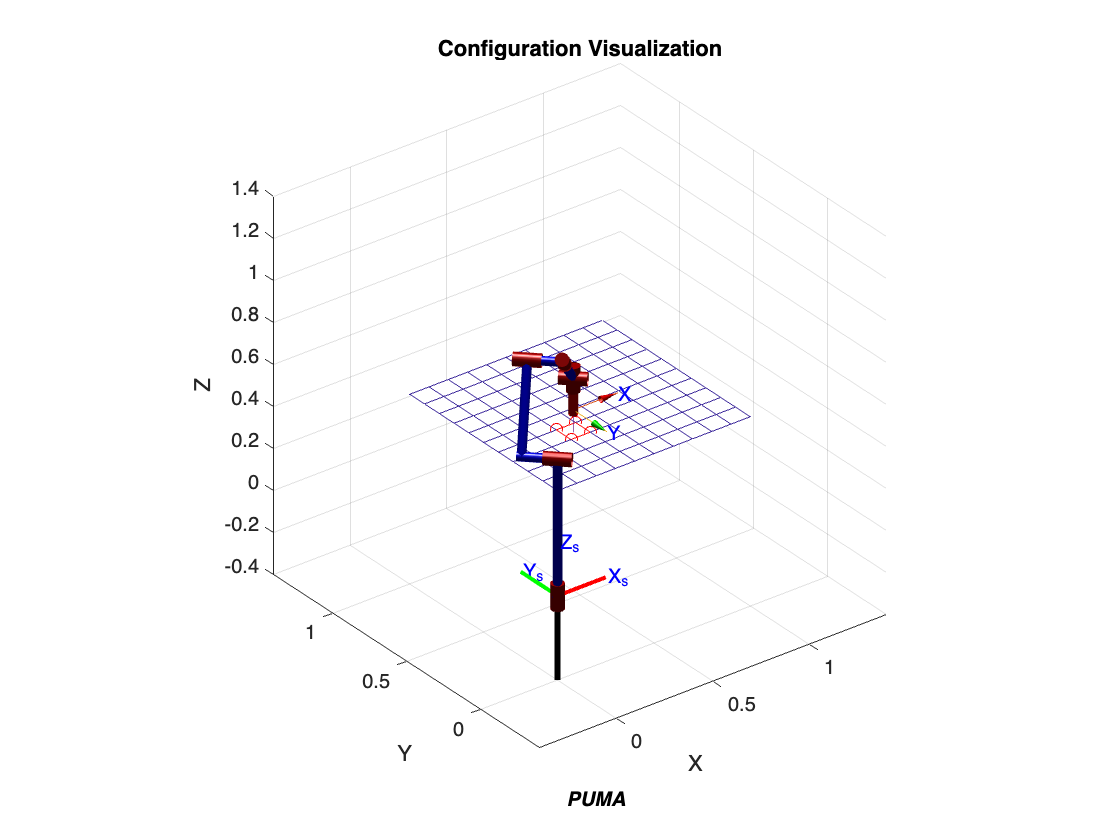

    % Angular velocities of robot manipulator joints
    % theta_deria = PUMA_ivkine(V_b_e, theta_current, joint_velocity_max);
    theta_deria = PUMA_ivkine(v, theta_current, joint_velocity_max);
    
    % Update angles of robot manipulator joints
    theta_current = theta_current + theta_deria*(1/Hz);
    
    % Update pose of robot end-effector
    T_s_e_current = PUMA_fkine(theta_current);
    
    % Plot new pose of end-effector
    figure(1)
    PUMA.plot(theta_current,'scale',0.3);
    i = i + 1;
end